all_diss = [];
all_P = [];
all_wind = [];
min_diss_ob = [];
min_diss_theo = [];
lat = [];
lon = [];


for x = 4:19  % adjust as needed
    data_file_num = x;

    % Select filename and QC file
    if data_file_num == 4
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0004-D.nc' ; qc_file = 'diss_qc_4.mat';
    elseif data_file_num == 5
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0005-C.nc' ; qc_file = 'diss_qc_5.mat';
    elseif data_file_num == 6
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0006-D.nc' ; qc_file = 'diss_qc_6.mat';
    elseif data_file_num == 7
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0007-C.nc' ; qc_file = 'diss_qc_7.mat';
    elseif data_file_num == 8
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0008-C.nc' ; qc_file = 'diss_qc_8.mat';
    elseif data_file_num == 9
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0009-C.nc' ; qc_file = 'diss_qc_9.mat';
    elseif data_file_num == 10
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0010-C.nc' ; qc_file = 'diss_qc_10.mat';
    elseif data_file_num == 11
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0011-C.nc' ; qc_file = 'diss_qc_11.mat';
    elseif data_file_num == 12
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0012-C.nc' ; qc_file = 'diss_qc_12.mat';
    elseif data_file_num == 13
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0013-C.nc' ; qc_file = 'diss_qc_13.mat';
    elseif data_file_num == 14
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0014-C.nc' ; qc_file = 'diss_qc_14.mat';
    elseif data_file_num == 15
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0015-C.nc' ; qc_file = 'diss_qc_15.mat';
    elseif data_file_num == 16
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0016-C.nc' ; qc_file = 'diss_qc_16.mat';
    elseif data_file_num == 17
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0017-C.nc' ; qc_file = 'diss_qc_17.mat';
    elseif data_file_num == 18
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0018-C.nc' ; qc_file = 'diss_qc_18.mat';
    elseif data_file_num == 19
        ncfilename = 'SUBFEX24-uCTD-binavg-slow-0019-C.nc' ; qc_file = 'diss_qc_19.mat';
    end

    % Load QC and NetCDF Data
    load(qc_file);
    RHO = ncread(ncfilename,'RHO');
    SIGMA_0 = ncread(ncfilename,'SIGMA_0');
    pressure = ncread(ncfilename,'pressure');
    station_number = ncread(ncfilename,'station_number');
    profile_start_datetime = ncread(ncfilename,'profile_start_datetime');
    time_ship = ncread('underway_met_subfex24.nc','time');
    wind_tru = ncread('underway_met_subfex24.nc','TW');

    station_best_profile = station_best_profile(station_best_profile ~= 0);
    station_list = unique(station_number(station_number ~= 0));  % [1, 3, 5, 7]
    time_best_profile = cell(length(max(station_list)), 1);

    for idx = 1:length(station_list)   % idx = 1, 2, 3, 4, 5
        i = station_list(idx);         % i = 1, 3, 5, 7,9
        column_numbers = find(station_number == i);
        column_number = column_numbers(station_best_profile(idx));  % use idx for station_best_profile
        time_best_profile{idx} = profile_start_datetime(column_number, :);
    end

    % Remove empty entries from time_best_profile
    non_empty_idx = ~cellfun(@isempty, time_best_profile);
    time_best_profile_clean = time_best_profile(non_empty_idx);

    % Convert to datetime
    datetime_profiles_best = datetime(time_best_profile_clean, ...
        'InputFormat', 'MM-dd-yyyy HH:mm:ss z', 'TimeZone', 'UTC');

    % Reformat
    time_best_profile_reformatted = datestr(datetime_profiles_best, 'yyyy-mm-dd HH:MM:SS');
    datetime_profiles_best = datetime(time_best_profile_reformatted, ...
        'InputFormat', 'yyyy-MM-dd HH:mm:ss', 'TimeZone', 'UTC')

    % Round to the nearest 15 seconds
    rounded_seconds = round(second(datetime_profiles_best) / 15) * 15;
    time_best_profile_rounded = datetime_profiles_best - seconds(second(datetime_profiles_best)) + seconds(rounded_seconds);
    time_zone = 'UTC';
    time_in_seconds = time_ship;

    % ship time is seconds since ship data is turned on --- convert into
    % UTC datetime
    ref_time_str = '2024-06-24 22:33:06'; 
    ref_time = datetime(ref_time_str, 'InputFormat', 'yyyy-MM-dd HH:mm:ss', 'TimeZone', time_zone);
    datetime_ship = ref_time + seconds(time_in_seconds);

    % Round to the nearest 15 seconds
    ship_rounded_seconds = round(second(datetime_ship) / 15) * 15;
    datetime_ship_rounded = datetime_ship - seconds(second(datetime_ship)) + seconds(ship_rounded_seconds);
    % Match with ship wind data
    time_ship = ncread('underway_met_subfex24.nc','time');
    wind_tru = ncread('underway_met_subfex24.nc','TW');
    ref_time = datetime('2024-06-24 22:33:06', 'InputFormat', 'yyyy-MM-dd HH:mm:ss', 'TimeZone', 'UTC');
    datetime_ship = ref_time + seconds(time_ship);
    datetime_ship_rounded = datetime_ship - seconds(second(datetime_ship)) + ...
        seconds(round(second(datetime_ship)/15)*15);

    [isMatch, idx_in_profiles] = ismember(datetime_ship_rounded, time_best_profile_rounded);
    wind_tru_matched = wind_tru(isMatch)

    % Remove all-NaN columns
    P_avg_best(:, all(isnan(P_avg_best), 1)) = [];
    diss_avg_best(:, all(isnan(diss_avg_best), 1)) = [];

    % Flatten and append data
    all_diss = [all_diss; log10(diss_avg_best(:))];
    all_P = [all_P; P_avg_best(:)];
    all_wind = [all_wind; repmat(wind_tru_matched(:), size(P_avg_best,1), 1)];

    stress_tru_matched = stresslp(wind_tru_matched,11);
    u_star = sqrt(stress_tru_matched/1025.5);
    karman = 0.41

    diss_theoretical = cell(length(unique(station_number)),1);
    diss_observed = cell(length(unique(station_number)),1);
    P_avg_best(:, all(isnan(P_avg_best), 1)) = [];
    diss_avg_best(:, all(isnan(diss_avg_best), 1)) = [];

    for i= 1:length(station_list)
        diss_theoretical{i} = log10(u_star(i)^3/(karman * min(P_avg_best(:,i))));
        diss_observed{i} = log10(min(diss_avg_best(:,i)));
    end

    diss_theoretical = cell2mat(diss_theoretical);
    diss_observed = cell2mat(diss_observed);

    min_diss_ob = [min_diss_ob; diss_observed(:)];
    min_diss_theo = [min_diss_theo; diss_theoretical(:)];

end

datetime_profiles_best = 7×1 datetime array
   30-Jun-2024 17:47:46
   30-Jun-2024 18:05:03
   30-Jun-2024 18:16:07
   30-Jun-2024 18:25:07
   30-Jun-2024 18:34:35
   30-Jun-2024 18:47:11
   30-Jun-2024 18:55:34


wind_tru_matched =     2.2000
    2.8000
    3.0000
    2.0000
    2.3000
    2.5000
    3.1000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   30-Jun-2024 19:47:14
   30-Jun-2024 19:58:17
   30-Jun-2024 20:12:39
   30-Jun-2024 20:21:04
   30-Jun-2024 20:30:14
   30-Jun-2024 20:39:32
   30-Jun-2024 20:48:18
   30-Jun-2024 20:55:07
   30-Jun-2024 21:03:22


wind_tru_matched =     5.4000
    4.8000
    5.2000
    5.5000
    6.2000
    4.2000
    6.6000
    6.1000
    3.4000


karman = 0.4100

datetime_profiles_best = 7×1 datetime array
   30-Jun-2024 21:37:17
   30-Jun-2024 21:49:40
   30-Jun-2024 21:59:24
   30-Jun-2024 22:06:38
   30-Jun-2024 22:16:33
   30-Jun-2024 22:30:42
   30-Jun-2024 22:40:22


wind_tru_matched =     4.9000
    6.1000
    7.5000
    4.6000
    3.3000
    1.0000
    0.9000


karman = 0.4100

datetime_profiles_best = 5×1 datetime array
   30-Jun-2024 23:40:30
   01-Jul-2024 00:03:02
   01-Jul-2024 00:23:23
   01-Jul-2024 00:42:11
   01-Jul-2024 00:59:21


wind_tru_matched =    11.0000
    2.6000
    9.0000
    6.0000
    0.8000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   01-Jul-2024 16:12:13
   01-Jul-2024 16:29:00
   01-Jul-2024 16:44:52
   01-Jul-2024 17:00:25
   01-Jul-2024 17:13:01
   01-Jul-2024 17:24:33
   01-Jul-2024 17:39:22
   01-Jul-2024 17:54:57
   01-Jul-2024 18:09:04


wind_tru_matched =     2.6000
    3.0000
    2.9000
    1.7000
    2.5000
    1.0000
    3.2000
    2.6000
    4.1000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   01-Jul-2024 19:27:59
   01-Jul-2024 19:43:17
   01-Jul-2024 20:02:34
   01-Jul-2024 20:14:37
   01-Jul-2024 20:24:38
   01-Jul-2024 20:37:09
   01-Jul-2024 20:47:04
   01-Jul-2024 20:55:43
   01-Jul-2024 21:05:38


wind_tru_matched =     8.1000
    5.0000
    8.8000
   10.6000
   10.3000
   11.4000
    9.2000
   12.7000
    8.6000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   01-Jul-2024 22:11:01
   01-Jul-2024 22:27:06
   01-Jul-2024 22:40:08
   01-Jul-2024 22:52:04
   01-Jul-2024 23:04:35
   01-Jul-2024 23:19:02
   01-Jul-2024 23:39:33
   01-Jul-2024 23:53:49
   02-Jul-2024 00:11:32


wind_tru_matched =    11.3000
   11.9000
   10.2000
    6.9000
    7.4000
    9.2000
    7.8000
    0.6000
    4.7000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   02-Jul-2024 15:45:15
   02-Jul-2024 16:02:00
   02-Jul-2024 16:16:58
   02-Jul-2024 16:30:31
   02-Jul-2024 16:47:24
   02-Jul-2024 17:03:46
   02-Jul-2024 17:16:02
   02-Jul-2024 17:27:07
   02-Jul-2024 17:44:19


wind_tru_matched =     0.8000
    0.7000
    1.3000
    1.6000
    1.4000
    0.9000
    1.0000
    0.3000
    1.8000


karman = 0.4100

datetime_profiles_best = 8×1 datetime array
   02-Jul-2024 19:03:42
   02-Jul-2024 19:17:55
   02-Jul-2024 19:33:32
   02-Jul-2024 19:49:54
   02-Jul-2024 20:06:18
   02-Jul-2024 20:19:58
   02-Jul-2024 20:37:31
   02-Jul-2024 20:51:09


wind_tru_matched =     1.7000
    3.5000
    4.0000
    3.4000
    3.7000
    4.1000
    4.4000
    4.1000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   02-Jul-2024 22:26:40
   02-Jul-2024 22:39:48
   02-Jul-2024 22:55:47
   02-Jul-2024 23:16:45
   02-Jul-2024 23:30:07
   02-Jul-2024 23:49:30
   03-Jul-2024 00:04:38
   03-Jul-2024 00:14:23
   03-Jul-2024 00:30:22


wind_tru_matched =     2.4000
    4.0000
    3.0000
    2.3000
    0.5000
    2.1000
    0.9000
    0.9000
    2.0000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   03-Jul-2024 15:42:00
   03-Jul-2024 15:59:15
   03-Jul-2024 16:14:13
   03-Jul-2024 16:39:22
   03-Jul-2024 16:55:40
   03-Jul-2024 17:10:26
   03-Jul-2024 17:23:00
   03-Jul-2024 17:35:23
   03-Jul-2024 17:48:57


wind_tru_matched =     2.1000
    1.1000
    0.8000
    0.6000
    1.6000
    2.1000
    2.3000
    2.7000
    3.0000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   04-Jul-2024 00:39:16
   04-Jul-2024 00:50:58
   04-Jul-2024 01:05:25
   04-Jul-2024 01:22:58
   04-Jul-2024 01:38:51
   04-Jul-2024 01:54:39
   04-Jul-2024 02:09:39
   04-Jul-2024 02:21:30
   04-Jul-2024 02:40:25


wind_tru_matched =     2.3000
    2.6000
    1.8000
    1.8000
    0.4000
    2.5000
    0.5000
    0.6000
    2.4000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   04-Jul-2024 15:28:10
   04-Jul-2024 15:45:42
   04-Jul-2024 15:59:40
   04-Jul-2024 16:14:24
   04-Jul-2024 16:33:07
   04-Jul-2024 16:47:48
   04-Jul-2024 17:03:33
   04-Jul-2024 17:19:35
   04-Jul-2024 17:32:03


wind_tru_matched =     0.5000
    1.8000
    0.4000
    2.0000
    3.0000
    2.4000
    4.0000
    4.8000
    5.0000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   04-Jul-2024 22:02:04
   04-Jul-2024 22:16:47
   04-Jul-2024 22:29:35
   04-Jul-2024 22:41:56
   04-Jul-2024 22:52:27
   04-Jul-2024 23:10:48
   04-Jul-2024 23:23:13
   04-Jul-2024 23:35:27
   04-Jul-2024 23:47:12


wind_tru_matched =     4.6000
    6.1000
    6.4000
    8.4000
    9.2000
    9.5000
   10.1000
    9.9000
    7.1000


karman = 0.4100

datetime_profiles_best = 9×1 datetime array
   05-Jul-2024 15:58:27
   05-Jul-2024 16:12:38
   05-Jul-2024 16:34:15
   05-Jul-2024 16:51:53
   05-Jul-2024 17:04:43
   05-Jul-2024 17:21:47
   05-Jul-2024 17:36:13
   05-Jul-2024 17:50:39
   05-Jul-2024 18:04:22


wind_tru_matched =     0.5000
    0.5000
    5.0000
    0.5000
    1.4000
    0.9000
    1.1000
    2.8000
    3.6000


karman = 0.4100

datetime_profiles_best = 5×1 datetime array
   05-Jul-2024 23:17:39
   05-Jul-2024 23:48:01
   06-Jul-2024 00:11:48
   06-Jul-2024 00:34:59
   06-Jul-2024 00:50:22


wind_tru_matched =     8.9000
    8.2000
    5.6000
    4.4000
    3.3000


karman = 0.4100

% Remove any remaining NaNs from the concatenated data
valid_idx = ~isnan(all_diss) & ~isnan(all_P);
size(all_wind)

ans =         3406           1


size(all_P)

ans =         3406           1


size(all_diss)

ans =         3406           1


size(valid_idx)

ans =         3406           1


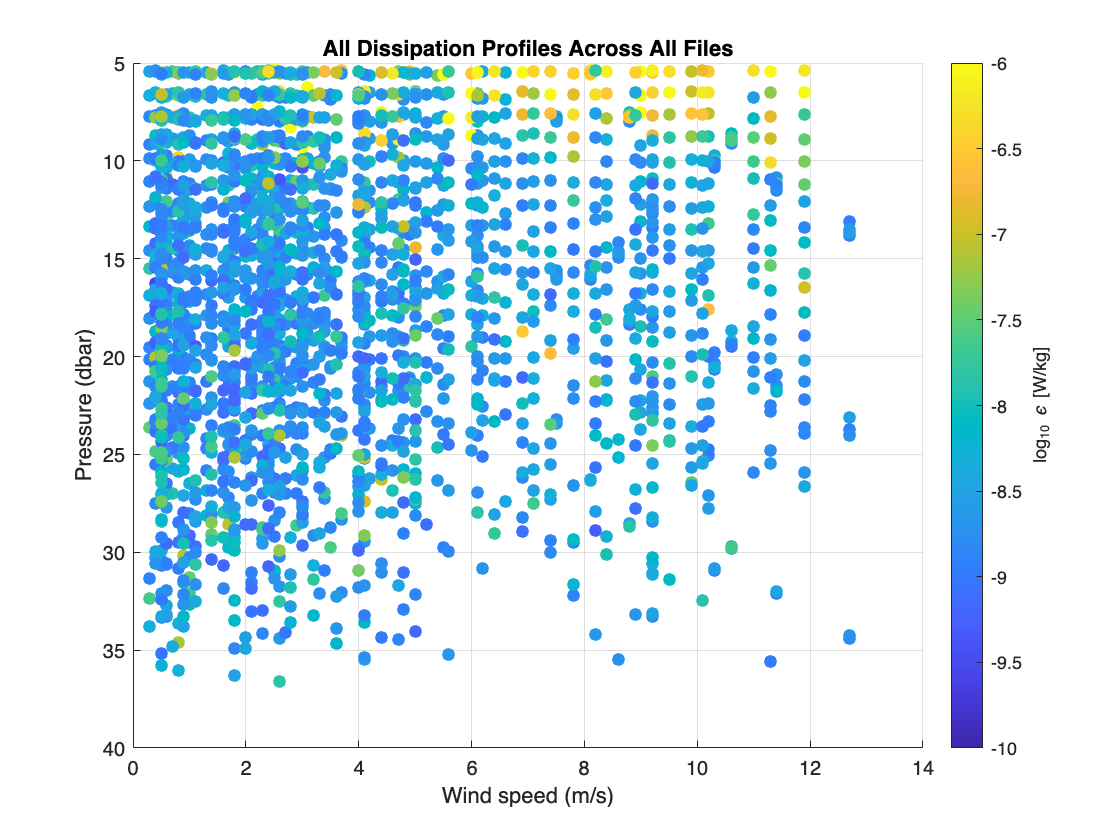



figure;
scatter(all_wind(valid_idx), all_P(valid_idx), 40,(all_diss(valid_idx)), 'filled');
colormap parula;
c = colorbar;
caxis([-10, -6]); % or adjust range as needed
ylabel(c, 'log_{10} \epsilon [W/kg]');
xlabel('Wind speed (m/s)');
ylabel('Pressure (dbar)');
title('All Dissipation Profiles Across All Files');
set(gca, 'YDir', 'reverse');  % Pressure increases downward
grid on;

%%Theoretical Dissipation
hold off;

figure();
scatter(min_diss_ob, min_diss_theo, 40, 'filled');
xlabel('Observed log_{10}(\epsilon) [W/kg]');
ylabel('Theoretical log_{10}(\epsilon) [W/kg]');
grid on;


%Find correlation coeficients and line of best fit
R = corrcoef(min_diss_ob, min_diss_theo);
R_value = R(1,2) % Extract R value

R_value = 0.4645

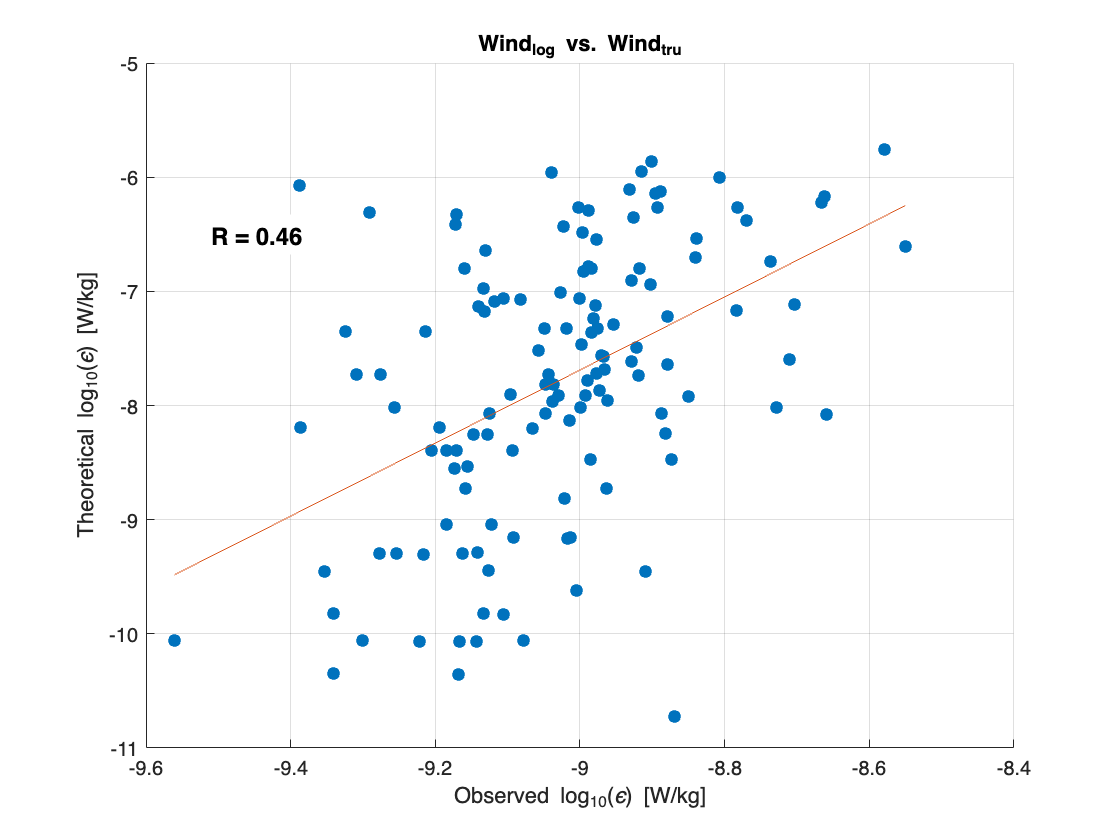


Fit = polyfit(min_diss_ob, min_diss_theo,1); 
hold on;
plot(min_diss_ob, polyval(Fit,min_diss_ob))
title('Wind_{log} vs. Wind_{tru}')
xpos = min(min_diss_ob) + 0.05 * (max(min_diss_ob) - min(min_diss_ob)); 
ypos = min(min_diss_theo) + 0.85 * (max(min_diss_theo) - min(min_diss_theo)); 
text(xpos, ypos, sprintf('R = %.2f', R_value), 'FontSize', 12, ...
    'FontWeight', 'bold', 'Color', 'k', 'BackgroundColor', 'w')
%drawnow;
hold off;


slope = Fit(1);
disp(['Slope of best-fit line: ', num2str(slope)]);

Slope of best-fit line: 3.2
